## **Jensen Wake Model.**

**References:  **Design of a Simple Wake Model for the Wind Farm Layout Optimization Considering the Wake Meandering Effect

% Parameters [INPUTS]
k = 0.075 % Wake Decay Coefficient [-]

k = 0.0750

D = 80 % Rotor Diameter [m]

D = 80

Uinf = 10 % Free-stream Velocity [m/s]

Uinf = 10

Ct = 0.75 % Cofficient of Thrust [-]

Ct = 0.7500

s = linspace(1,10,100) % Normalized Distance [-]

s =     1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545



% Parameters [OUTPUTS] 
Dwake = D*(1+2*k*s)

Dwake =    92.0000   93.0909   94.1818   95.2727   96.3636   97.4545   98.5455   99.6364  100.7273  101.8182  102.9091  104.0000  105.0909  106.1818  107.2727  108.3636  109.4545  110.5455  111.6364  112.7273  113.8182  114.9091  116.0000  117.0909  118.1818  119.2727  120.3636  121.4545  122.5455  123.6364  124.7273  125.8182  126.9091  128.0000  129.0909  130.1818  131.2727  132.3636  133.4545  134.5455  135.6364  136.7273  137.8182  138.9091  140.0000  141.0909  142.1818  143.2727  144.3636  145.4545


Udef = Uinf*((1-sqrt(1-Ct))./(1+2*k*s).^2)

Udef =     3.7807    3.6926    3.6076    3.5254    3.4461    3.3693    3.2952    3.2234    3.1540    3.0867    3.0216    2.9586    2.8975    2.8382    2.7808    2.7251    2.6711    2.6186    2.5677    2.5182    2.4702    2.4235    2.3781    2.3340    2.2911    2.2494    2.2088    2.1693    2.1309    2.0934    2.0570    2.0215    1.9868    1.9531    1.9203    1.8882    1.8570    1.8265    1.7967    1.7677    1.7394    1.7117    1.6848    1.6584    1.6327    1.6075    1.5829    1.5589    1.5354    1.5125


U_real = Uinf*(1.-Udef)

U_real =   -27.8072  -26.9263  -26.0758  -25.2544  -24.4607  -23.6935  -22.9516  -22.2340  -21.5396  -20.8673  -20.2164  -19.5858  -18.9747  -18.3824  -17.8081  -17.2510  -16.7105  -16.1859  -15.6767  -15.1821  -14.7017  -14.2349  -13.7812  -13.3401  -12.9112  -12.4941  -12.0882  -11.6931  -11.3086  -10.9343  -10.5697  -10.2145   -9.8685   -9.5312   -9.2025   -8.8821   -8.5695   -8.2647   -7.9673   -7.6771   -7.3939   -7.1175   -6.8476   -6.5840   -6.3265   -6.0750   -5.8293   -5.5892   -5.3545   -5.1250


U_co = Uinf./U_real

U_co =    -0.3596   -0.3714   -0.3835   -0.3960   -0.4088   -0.4221   -0.4357   -0.4498   -0.4643   -0.4792   -0.4946   -0.5106   -0.5270   -0.5440   -0.5615   -0.5797   -0.5984   -0.6178   -0.6379   -0.6587   -0.6802   -0.7025   -0.7256   -0.7496   -0.7745   -0.8004   -0.8273   -0.8552   -0.8843   -0.9146   -0.9461   -0.9790   -1.0133   -1.0492   -1.0867   -1.1259   -1.1669   -1.2100   -1.2551   -1.3026   -1.3525   -1.4050   -1.4604   -1.5188   -1.5806   -1.6461   -1.7155   -1.7892   -1.8676   -1.9512


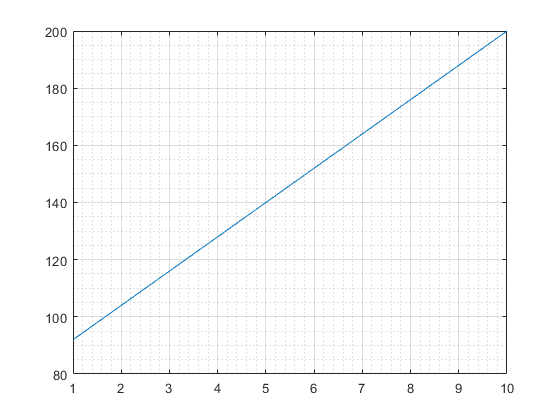

plot(s,Dwake)
grid on  
grid minor

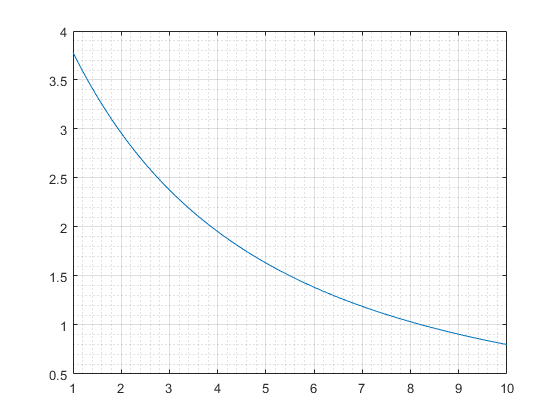

plot(s,Udef)
grid on  
grid minor

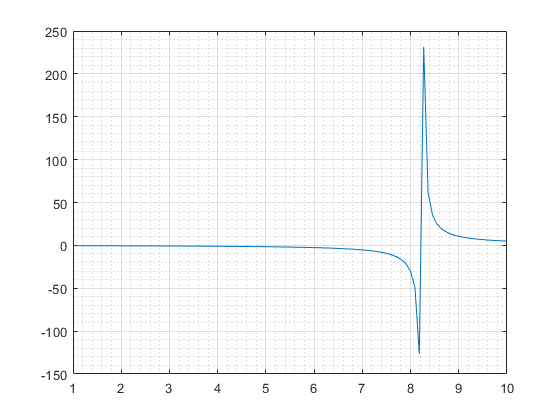

plot(s,U_co)
grid on  
grid minor